clear all
close all
clc

ctr_freq = 4000;
ctr_time = 1/ctr_freq;
max_vel = 3.3/ctr_freq;
endtime = 2;
constime = 0; 
amp = (endtime/2 + constime)*max_vel*ctr_freq/2/2;
[traj_pos, traj_vel, traj_acc] = lspb_core_InertiaID(amp,-amp,endtime,ctr_freq,max_vel);
traj_vel = traj_vel*ctr_freq;
traj_acc = traj_acc*ctr_freq*ctr_freq;
csvwrite('InertiaTraj\traj_pos.csv', traj_pos);
csvwrite('InertiaTraj\traj_vel.csv', traj_vel)
csvwrite('InertiaTraj\traj_acc.csv', traj_acc)


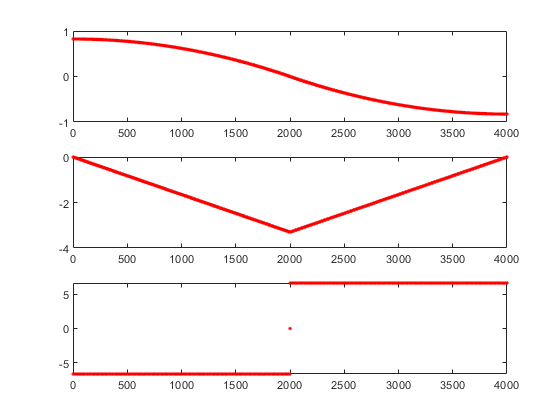

figure
subplot(311)
plot(traj_pos, 'r.')
subplot(312)
plot(traj_vel, 'r.')
subplot(313)
plot(traj_acc, 'r.')